## Lab1 Report

## Students :

- Ivar Jönsson ivajns-9

### Task 1

Generate three periods of a continuous-time sinusoid with amplitude A = 2, fre-

quency f = 3 Hz (ω = 2πf), and phase φ = π/3. In addition, create a second sinu-

soid of equal length (in time). The second sinusoid should have amplitude A = 2,

frequency f = 1 Hz, and phase φ = 0. Plot these in the same figure, one of the

signals should be dashed while the other should be solid, see `help plot`, and `help`

`hold`. Remember to choose the time vector t, so that the figures look good

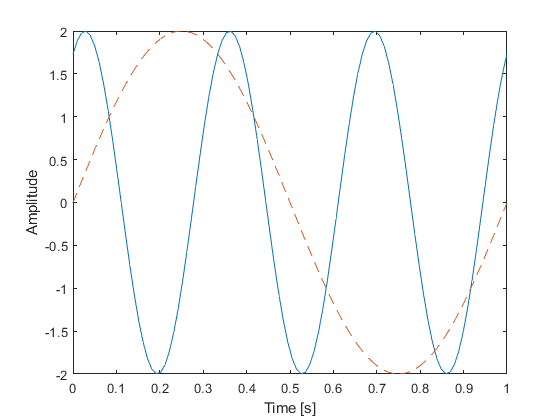

task1 = figure('Name','Task 1');
figure(task1)
% Define a general sinus 
sinusoid = @(A,Omega,phase,t) A*sin(Omega.*t+phase);
t = linspace(0,1,100);
sig_1 = sinusoid(2,3.*2.*pi,pi./3,t);
sig_2 = sinusoid(2,1.*2.*pi,0,t);

plot(t,sig_1);
hold on
fp = plot(t,sig_2,'--');
ylabel("Amplitude");    % Since there is no better lable
xlabel("Time [s]")
ylabel("Amplitude")
hold off

### Task 2

Generate the following three continuous-time signals for the time interval −1 ≤t ≤2

• x(t) = cos(6πt)

• y(t) = |t|^`1/3`

• z(t) = x(t)y(t)

Plot the three signals in the same window, but in three different figures, see `subplot`

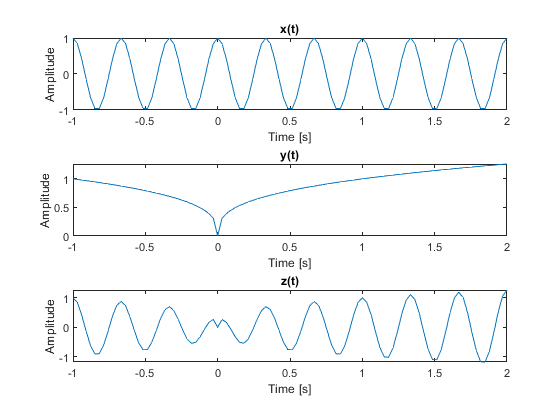

task2 = figure('Name',"Task 2");
figure(task2);
time = linspace(-1,2,100);
x = @(t) cos(6.*pi.*t);
y = @(t) abs(t).^(1/3);
z = @(t) x(t).*y(t);
t = [-1,2];
title("Task 2");
subplot(3,1,1);
plot(time,x(time));
ylabel("Amplitude");    % Since there is no better lable
title("x(t)");
xlabel("Time [s]");
subplot(3,1,2);
plot(time,y(time));
ylabel("Amplitude");    % Since there is no better lable
title("y(t)");
xlabel("Time [s]");
subplot(3,1,3);
plot(time,z(time));
ylabel("Amplitude");    % Since there is no better lable
title("z(t)");
xlabel("Time [s]");

### Task 3

Repeat Exercise 2 for the three discrete-time signals obtained by sampling x(t), y(t),

and z(t) using Ts = 1/5 s, i.e., illustrate

• x[n] = x(nTs)

• y[n] = y(nTs)

• z[n] = z(nTs)

Remember to label the axes carefully

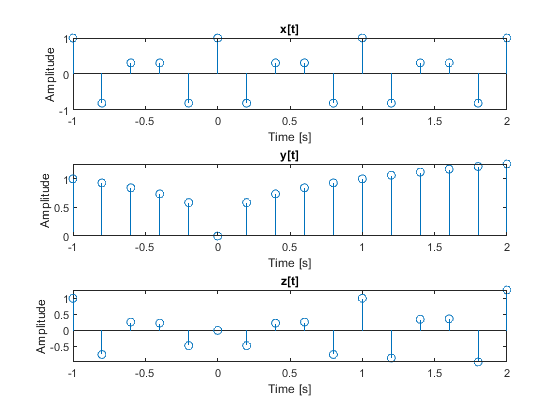

task3 = figure("Name","Task 3");

times = -1:1/5:2;
disc_x = x(times);
disc_y = y(times);
disc_z = z(times);
subplot(3,1,1);
stem(times,disc_x);
ylabel("Amplitude");    % Since there is no better lable
xlabel("Time [s]");
title("x[t]");
subplot(3,1,2);
stem(times,disc_y);
ylabel("Amplitude");    % Since there is no better lable
xlabel("Time [s]");
title("y[t]");
subplot(3,1,3);
stem(times,disc_z);
ylabel("Amplitude");    % Since there is no better lable
xlabel("Time [s]");
title("z[t]");

### Task 4

A particular LTI system, call it System 1, is described through the input-output

relation

y[n] =1/8( x[n] + x[n −1] + x[n −2] + x[n −3] + x[n −4] + x[n −5] + x[n −6] + x[n −7])

Find the impulse response, h1[n], of System 1 (analytically).

Simple, 


$$Y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack \Rightarrow h\left\lbrack n\right\rbrack =\frac{1}{8}\left(\delta \left\lbrack n\right\rbrack +\delta \left\lbrack n-1\right\rbrack +\delta \left\lbrack n-2\right\rbrack +\delta \left\lbrack n-3\right\rbrack +\delta \left\lbrack n-4\right\rbrack +\delta \left\lbrack n-5\right\rbrack +\delta \left\lbrack n-6\right\rbrack +\delta \left\lbrack n-7\right\rbrack \right)$$


And expressed in code it is

h = (1./8)*ones([1,8]);
h_handle = @(n) (n<=7 & n>= 0).*(1./8);
differential_signal = (1./8)*ones([1,8]);

Helpers

unit_sig = @(start_p,end_p,delay) start_p:1:end_p == delay;
step_sig = @(start_p,end_p,plat_start,plat_end) (start_p:1:end_p <= plat_end) - (start_p:1:end_p < plat_start);
convolve = @(x,h,n,k_start,k_end) h(k_start:1:k_end).*(x(n-(k_end-k_start):1:n));

### Task 5

Use Matlab to find the output obtained by feeding the input signal

x[n] =.5^n

for 0 ≤n ≤10

0 otherwise

through System 1. Illustrate the input and output signals in an appropriate way.

time_steps = 15;
time = 0:1:time_steps;
task5 = figure("Name","task 5");
% Define a new input signal
sig_in = @(x) (x <= 10 ).*( x >= 0).*(0.5.^x);

out = conv(sig_in(time),h_handle(0:1:8),"full");

out =     0.1250    0.1875    0.2188    0.2344    0.2422    0.2461    0.2480    0.2490    0.1245    0.0623    0.0311    0.0155    0.0077    0.0038    0.0018    0.0009    0.0004    0.0001         0         0         0         0         0         0


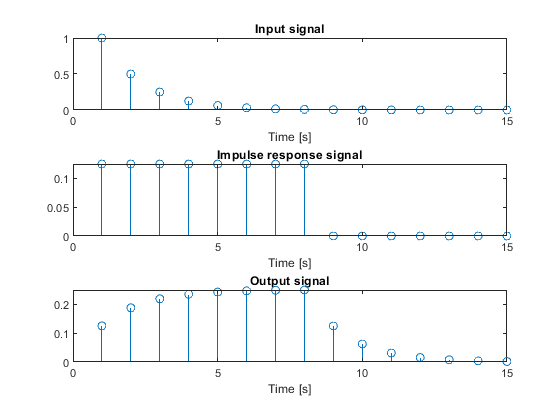

% Plot things
figure(task5);
subplot(3,1,1);
stem(sig_in(time));
xlim([0,time_steps])
xlabel("Time [s]");
title("Input signal");
subplot(3,1,2);
stem(h_handle(time));
xlim([0,time_steps])
xlabel("Time [s]");
title("Impulse response signal");
subplot(3,1,3);
stem(out);
xlim([0,time_steps])
xlabel("Time [s]");
title("Output signal");

### Task 6

Repeat Exercise 5, but this time by using the input signal x2[n] = x[n + 2].

time = 0:1:time_steps;
% Define the new input signal
sig_in_2 = @(n)sig_in(n+2);
out = conv(sig_in_2(time),h_handle(0:1:8))

out =     0.0312    0.0469    0.0547    0.0586    0.0605    0.0615    0.0620    0.0623    0.0311    0.0155    0.0077    0.0038    0.0018    0.0009    0.0004    0.0001         0         0         0         0         0         0         0         0


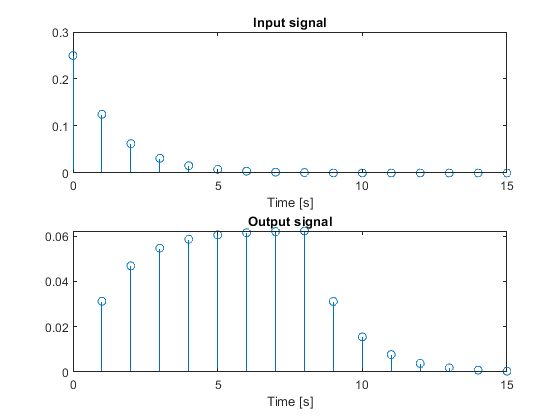

task6 = figure("Name","task 6");


% Plot things
figure(task6);
subplot(2,1,1);
stem(time,sig_in_2(time));
xlim([0,time_steps])
xlabel("Time [s]");
title("Input signal");
subplot(2,1,2);
plt = stem(out);
xlim([0,time_steps])

xlabel("Time [s]");
title("Output signal");

### Task 7

Repeat Exercise 5, but this time consider a system with impulse response

h2[n] = h1[−n]

h2_handle = @(n) h_handle(-n);

Now the impulse response is


$$\begin{array}{l}
h\left\lbrack n\right\rbrack =\frac{1}{8}\left(\delta \left\lbrack -n\right\rbrack +\delta \left\lbrack -n-1\right\rbrack +\delta \left\lbrack -n-2\right\rbrack +\delta \left\lbrack -n-3\right\rbrack +\delta \left\lbrack -n-4\right\rbrack +\delta \left\lbrack -n-5\right\rbrack +\delta \left\lbrack -n-6\right\rbrack +\delta \left\lbrack -n-7\right\rbrack \right)\\

\end{array}$$


time = 0:1:time_steps;
out = conv(sig_in(time),h2_handle(time))

out =     0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


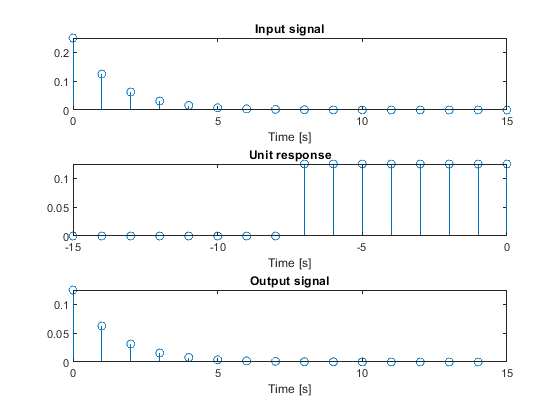




% Plot things
task7 = figure("Name","task 6");
figure(task7);
subplot(3,1,1);
stem(time,sig_in_2(time));
xlabel("Time [s]");
title("Input signal");
xlim([0,time_steps])
subplot(3,1,2);
stem(-time,h2_handle(-time));
xlabel("Time [s]");
title("Unit response");
subplot(3,1,3);
stem(time(1:time_steps),out(1,1:time_steps));
xlabel("Time [s]");
title("Output signal");

Now it only scales down n since it can't be a rolling average filter anny more. this is because -x where x is some offset never equals zero for  k >= 0 except for when x = 0 so it only scales the current value.

## Task 8

Repeat Exercise 5 but this time by using the input signal

x[n] = cos (π/8 n) + cos( π/4 n) for 0 ≤n ≤127

0 otherwise

Comment on the results, especially regarding the frequency content of the input and

output signals. Can you explain this behavior?

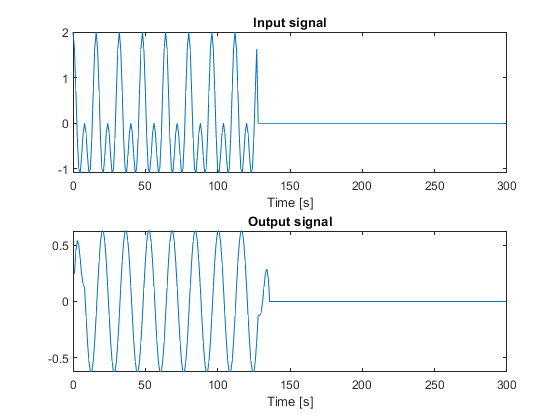

time_steps = 300;
time = 0:1:time_steps;
sig = @(n)(cos((pi/8).*n) + cos((pi/4).*n)).*(n <=127 & n >= 0);
out = conv(sig(time),h_handle(time),"full");


task8 = figure("Name","task 8");
% Plot things
figure(task8);
subplot(2,1,1);
plot(time,sig(time));
xlabel("Time [s]");
title("Input signal");
subplot(2,1,2);
plot(out);
xlim([0,time_steps])
xlabel("Time [s]");
title("Output signal");

It does not change the frequency since it's just a filter, this is one of the fundemental properties of FIR filters.

It does however change the amplitude and introduces a phase shift. this is due the fact that the derivative is an eigth of the original signal. 

### Task 9

In the file `eva.mat`, two Matlab variables `xl` and `xr` can be found. You can load these

into the workspace through the load command, see `help load`. `xl` and `xr` contains

the left and right channel of an audio segment sampled at 44,1 kHz. You can listen

to it in Matlab using the `sound` command,

`sound([xl,xr],44100)`

Feed both channels through System 1 and listen to the result. Comment briefly

on how you experience the processed audio signal.

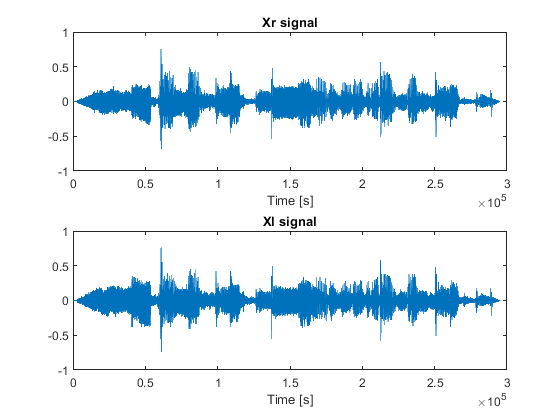

% Load the data
data = load("eva.mat",'xr','xl');
% Split the field
xr = data.xr;
xl = data.xl;
% Create output vectors for the system
out_xr = conv(xr,h_handle(0:1:10),"full"); 
out_xl = conv(xl,h_handle(0:1:10),"full"); 
% Convolve over the input data



% Plot original signal
task9 = figure("Name","task 9");
figure(task9);
subplot(2,1,1);
plot(1:length(xr),xr);
xlabel("Time [s]");
title("Xr signal");
subplot(2,1,2);
plot(1:length(xr),xl);
xlabel("Time [s]");
title("Xl signal");

And after the system we get

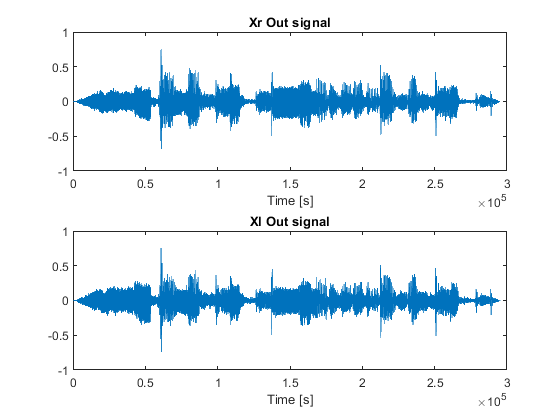

% Plot the output signals
task9_2 = figure("Name","task 9 2");
figure(task9_2);
subplot(2,1,1);
plot(out_xr);
xlabel("Time [s]");
title("Xr Out signal");
subplot(2,1,2);
plot(out_xl);
xlabel("Time [s]");
title("Xl Out signal");


% Play the sound
%sound([xl,xr],44100);
%sound([out_xl,out_xr],44100);

The processed audio seems more quiet, it also seems a bit more "muddy" as in it has been smoothed out a bit, removing some of the audio detail.